a = randi(100, 10, 2)

a =     19     9
     6    21
    38    57
    12    28
    49    95
    91    68
    40    10
     6    28
    74    26
    81    24


x = rand

x = 0.5861

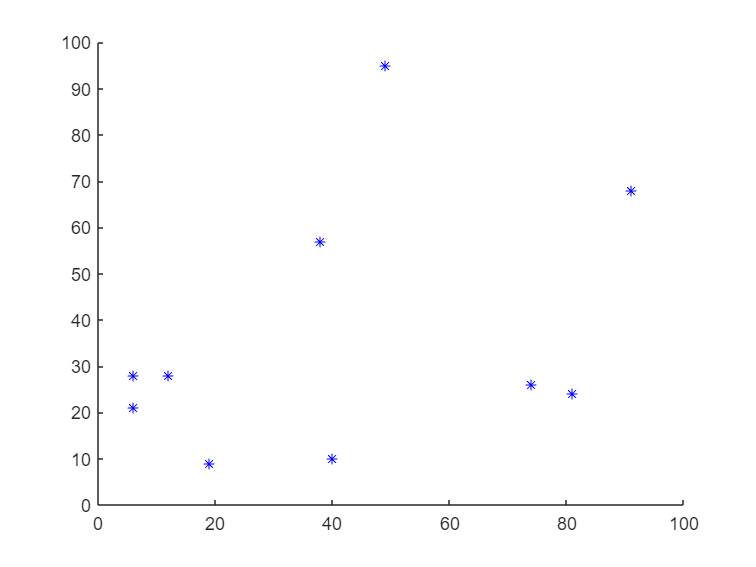

scatter(a(:,1),a(:,2),'b*');


rComm = 0;
D = squareform(pdist(a));

[commCells, adjMatrix] = communication(a, rComm);

tMass = 100;
nPart = 10;

Density = randi([1,1], 100, 100)

Density =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

region = randi([1,50], 2, 2)

region =     30    19
    20    35



calcDensity(Density, region, 2)

Error: File: calcDensity.m Line: 28 Column: 47
Invalid expression. Check for missing or extra characters.


agentPoints = assignAgentPoints(a, commCells, 100, 1, 10)
sum(sum(Density))

hold on;
for i = 1:size(agentPoints,1)
    scatter(agentPoints{i}(:,1), agentPoints{i}(:,2), 'g.')
end

calcCoverage(agentPoints,1,Density,sum(sum(Density)))
direction = randi([0,100],10,2);
direction = arrayfun( @(x) x / 100, direction)

velocity = randi(10,10,1)
dt = 0.1;
deltaPosX = direction(:,1) .* velocity * dt;
deltaPosY = direction(:,2) .* velocity * dt;
deltaPos = horzcat(deltaPosX, deltaPosY);

rate = 1;
deltaEnergy = velocity * -rate * dt;

%calcCentroids(agentPoints,calcMass(a),Density,a,1);

mass = calcMass(agentPoints,Density,1)
size(agentPoints{1}(:,1),1)

centroidsX = randi([0,0], size(agentPoints,1), 1);
centroidsY = randi([0,0], size(agentPoints,1), 1);

for i = 1:size(agentPoints,1)
    for j = 1:size(agentPoints{i}(:,1),1)
        centroidsX(i,1) = sum(agentPoints{i}(j,1)*mass(i))/mass(i);
        centroidsY(i,1) = sum(agentPoints{i}(j,2)*mass(i))/mass(i);
    end
end

centroids = horzcat(centroidsX, centroidsY);